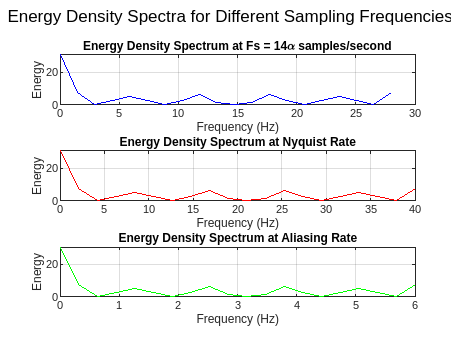

alpha = 1 + mod(236, 3);

% 1 (1)
t = linspace(0, 1/alpha, 1000);

ya = alpha * cos(2 * pi * 5 * alpha * t);
yb = (alpha / 2) * cos(2 * pi * 6 * alpha * t);
yc = (alpha / 4) * cos(2 * pi * 10 * alpha * t);

% Plot the waveforms in one single plot
plot(t, ya, 'b', t, yb, 'g', t, yc, 'r');
title('Waveforms');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Amplitude \alpha, Frequency 5\alpha Hz', 'Amplitude \alpha/2, Frequency 6\alpha Hz', 'Amplitude \alpha/4, Frequency 10\alpha Hz');
grid on;

% 1 (2)
y2 = ya + yb + yc;
plot(t, y2)
xlabel('Time (s)');
ylabel('Amplitude');

% 1 (3)

% Calculate the cumulative waveform
cumulative_waveform = alpha * cumsum(cos(2 * pi * 10 * alpha * t));

% Sampling frequencies
Fs_a = 14 * alpha;    
Fs_nyquist = 20 * alpha;  
Fs_aliasing = 6 * alpha;  

% Sample the cumulative waveform at different rates
n_a = 0:1/Fs_a:(1/alpha - 1/Fs_a);  % Time vector for (a)
n_nyquist = 0:1/Fs_nyquist:(1/alpha - 1/Fs_nyquist);  % Time vector for (b)
n_aliasing = 0:1/Fs_aliasing:(1/alpha - 1/Fs_aliasing);  % Time vector for (c)

sampled_waveform_a = alpha * cos(2 * pi * 10 * alpha * n_a);
sampled_waveform_b = alpha * cos(2 * pi * 10 * alpha * n_nyquist);
sampled_waveform_c = alpha * cos(2 * pi * 10 * alpha * n_aliasing);

subplot(3, 1, 1);
stem(n_a, sampled_waveform_a, 'b');
title('Discrete-time Waveform (Fs = 14\alpha samples/second)');
xlabel('Sample Index');
ylabel('Amplitude');

subplot(3, 1, 2);
stem(n_nyquist, sampled_waveform_b, 'g');
title('Discrete-time Waveform (Nyquist Rate)');
xlabel('Sample Index');
ylabel('Amplitude');

subplot(3, 1, 3);
stem(n_aliasing, sampled_waveform_c, 'r');
title('Discrete-time Waveform (Aliasing Rate)');
xlabel('Sample Index');
ylabel('Amplitude');

% % 1 (4)
% % Linear interpolation to reconstruct the signals
t_interp = linspace(0, 1/alpha, 1000);  % Interpolation time vector

interpolated_waveform_a = interp1(n_a, sampled_waveform_a, t_interp, 'linear');
interpolated_waveform_b = interp1(n_nyquist, sampled_waveform_b, t_interp, 'linear');
interpolated_waveform_c = interp1(n_aliasing, sampled_waveform_c, t_interp, 'linear');

subplot(3, 1, 1);
plot(t_interp, interpolated_waveform_a, 'b');
title('Interpolated Waveform (Fs = 14\alpha samples/second)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3, 1, 2);
plot(t_interp, interpolated_waveform_b, 'g');
title('Interpolated Waveform (Nyquist Rate)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3, 1, 3);
plot(t_interp, interpolated_waveform_c, 'r');
title('Interpolated Waveform (Aliasing Rate)');
xlabel('Time (s)');
ylabel('Amplitude');

% 1 (5)
% Time values for the duration of 1/α seconds
t = linspace(0, 1/alpha, 20);

% Calculate the waveforms (as before)
waveform_a = alpha * cos(5 * alpha * 2 * pi * t);
waveform_b = (alpha/2) * cos(6 * alpha * 2 * pi * t);
waveform_c = (alpha/4) * cos(10 * alpha * 2 * pi * t);
sum_waveform = waveform_a + waveform_b + waveform_c;

% Calculate the absolute value of the cumulative signal
abs_sum_waveform = abs(sum_waveform);

% Sampling frequency for each case
Fs_a = 14 * alpha;
Fs_b = 2 * max([5*alpha, 6*alpha, 10*alpha]);
Fs_c = 3 * alpha;

% Calculate the FFT for each sampled signal
fft_a = fft(abs_sum_waveform);
fft_b = fft(abs_sum_waveform);
fft_c = fft(abs_sum_waveform);

% Frequency values for FFT
freq_a = linspace(0, Fs_a, length(fft_a));
freq_b = linspace(0, Fs_b, length(fft_b));
freq_c = linspace(0, Fs_c, length(fft_c));

% Plotting the energy density spectrum
figure;

% Subplot (a)
subplot(3, 1, 1);
plot(freq_a, abs(fft_a), 'b');
title('Energy Density Spectrum at Fs = 14\alpha samples/second');
xlabel('Frequency (Hz)');
ylabel('Energy');
grid on;

% Subplot (b)
subplot(3, 1, 2);
plot(freq_b, abs(fft_b), 'r');
title('Energy Density Spectrum at Nyquist Rate');
xlabel('Frequency (Hz)');
ylabel('Energy');
grid on;

% Subplot (c)
subplot(3, 1, 3);
plot(freq_c, abs(fft_c), 'g');
title('Energy Density Spectrum at Aliasing Rate');
xlabel('Frequency (Hz)');
ylabel('Energy');
grid on;

sgtitle('Energy Density Spectra for Different Sampling Frequencies');


% Print the frequency values that are aliased and their aliased values
fprintf('For 3(a) and 3(c), the frequency 10α Hz is aliased to %f Hz.\n', mod(10*alpha, Fs_a));

For 3(a) and 3(c), the frequency 10α Hz is aliased to 20.000000 Hz.


fprintf('For 3(a) and 3(c), the frequency 5α Hz is aliased to %f Hz.\n', mod(5*alpha, Fs_a));

For 3(a) and 3(c), the frequency 5α Hz is aliased to 10.000000 Hz.




% Q 2
% Frequencies for "Do Re Mi Fa So La Ti Do"
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25];

% Duration of each note in seconds
note_duration = 0.5;

% Create an array to store the concatenated signal
concatenated_signal = [];

% Loop through the frequencies and generate tones
for freq = frequencies
    t = linspace(0, note_duration, round(44100 * note_duration)); % 44100 Hz sampling rate
    tone = sin(2 * pi * freq * t);
    concatenated_signal = [concatenated_signal, tone];
end

% Save the concatenated signal as a .wav file (44100 Hz)
audiowrite('sequence_44100Hz.wav', concatenated_signal, 44100);

% Repeat the process for other sampling rates (22050 Hz and 11025 Hz)
t_22050 = linspace(0, note_duration, round(22050 * note_duration));
t_11025 = linspace(0, note_duration, round(11025 * note_duration));

concatenated_signal_22050 = [];
concatenated_signal_11025 = [];

for freq = frequencies
    tone_22050 = sin(2 * pi * freq * t_22050);
    concatenated_signal_22050 = [concatenated_signal_22050, tone_22050];
    
    tone_11025 = sin(2 * pi * freq * t_11025);
    concatenated_signal_11025 = [concatenated_signal_11025, tone_11025];
end

% Save the concatenated signals as .wav files
audiowrite('sequence_22050Hz.wav', concatenated_signal_22050, 22050);
audiowrite('sequence_11025Hz.wav', concatenated_signal_11025, 11025);





% Q 3
% Load the original audio file
original_audio = audioread('Track00α.wav');

% Define the sampling rates for downsampling
sampling_rates = [22050, 11025, 5512.5]; % Half, 1/3rd, 1/6th of the original rate

% Perform downsampling and save audio files
for i = 1:length(sampling_rates)
    new_sampling_rate = sampling_rates(i);
    resampled_audio = resample(original_audio, new_sampling_rate, 44100);
    audiowrite(sprintf('resampled_%dHz.wav', new_sampling_rate), resampled_audio, new_sampling_rate);
end

% Define the upsampling factor
upsampling_factor = 2;

% Perform zero-padding upsampling and save audio file
upsampled_audio = resample(original_audio, upsampling_factor, 1);
audiowrite(sprintf('upsampled_%dx.wav', upsampling_factor), upsampled_audio, 44100);

